HW5 106010006 黃詩瑜 電機21

5.

使用rectangular window，


$$\begin{array}{l}
\Delta \omega =0\ldotp 2\pi \textrm{，0}\ldotp 2\pi =\frac{6\ldotp 2\pi }{L}\Rightarrow L=31\Rightarrow M=30\\
h_d \left\lbrack n\right\rbrack =\frac{\sin \left\lbrack 0\ldotp 4\pi \left(n-15\right)\right\rbrack }{\pi \left(n-15\right)}
\end{array}$$


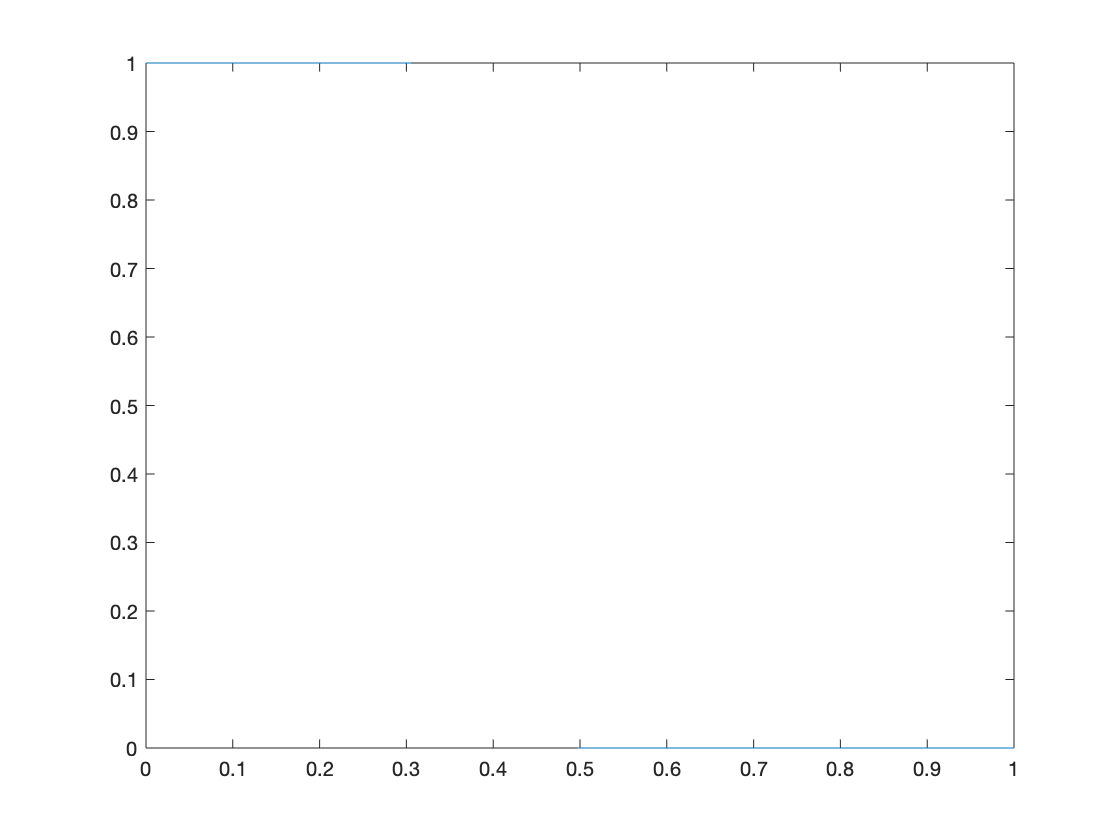

n=0:1:30;
h=0.4*pi*(sinc(0.4*pi*(n-15))./pi);
b = [0 0.3 0.5 1];  %輸入Ws和Wp的限制
a = [1 1 0 0];
bhi = fir2(30,b,a,rectwin(31));
H=freqz(bhi,1);
H=H';
om=linspace(0,pi,512);
ideal_H=[ones(1,157) NaN(1,97) zeros(1,258)]; %創一個ideal的low pass filter
plot(om/pi,ideal_H)

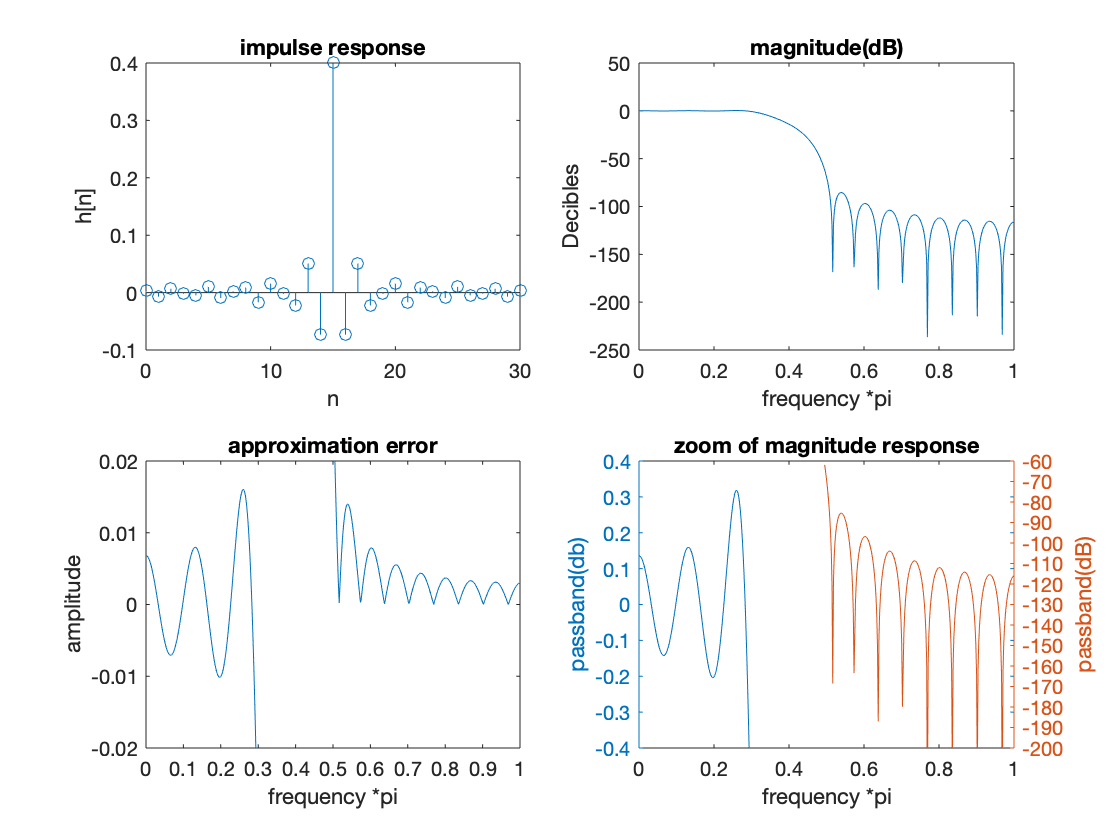

error=abs(H)-ideal_H; %把設計好的filter與ideal filter相減得error
Hr=20*log(abs(H));
H_zoom_r=[Hr(1:157) NaN(1,355)]; %此為待會zoom in所需的圖形
H_zoom_l=[NaN(1,253) Hr(254:512)];
figure
subplot(221)
stem(n,h)
title('impulse response')
xlabel('n')
ylabel('h[n]')
subplot(222)
plot(om/pi,20*log(abs(H)))
title('magnitude(dB)');
xlabel('frequency *pi')
ylabel('Decibles')
subplot(223)
plot(om/pi,error)
ylim([-0.02, 0.02]);
xticks([0:0.1:1])
title('approximation error');
xlabel('frequency *pi')
ylabel('amplitude')
subplot(224)
[AX,H1,H2]=plotyy(om/pi,H_zoom_r,om/pi,H_zoom_l);
set(AX(1),'YLim',[-0.4 0.4])
set(AX(2),'YLim',[-200 -60])
set(AX(1),'YTick',[-0.4:0.1:0.4])
set(AX(2),'YTick',[-200:10:-60])
ylabel(AX(1),'passband(db)') % left y-axis
ylabel(AX(2),'passband(dB)') % right y-axis
title('zoom of magnitude response');
xlabel('frequency *pi')

6.

(a)


$$\begin{array}{l}
\beta =0\ldotp 5842{\left(50-21\right)}^{0\ldotp 4} +0\ldotp 07886\left(50-21\right)=4\ldotp 5335\\
\Delta \omega =0\ldotp 2\pi \;,M=\frac{50-8}{2\ldotp 285\times 0\ldotp 2\pi }=29\ldotp 25\;\Rightarrow \textrm{choose}\;M=30\\
h_d \left\lbrack n\right\rbrack =\frac{\sin \left\lbrack 0\ldotp 4\pi \left(n-15\right)\right\rbrack }{\pi \left(n-15\right)},w\left\lbrack n\right\rbrack =\frac{I\left\lbrack 4\ldotp 5335\sqrt{1-{\left\lbrack \frac{\left(n-15\right)}{15}\right\rbrack }^2 }\right\rbrack }{I\left(4\ldotp 5335\right)}
\end{array}$$


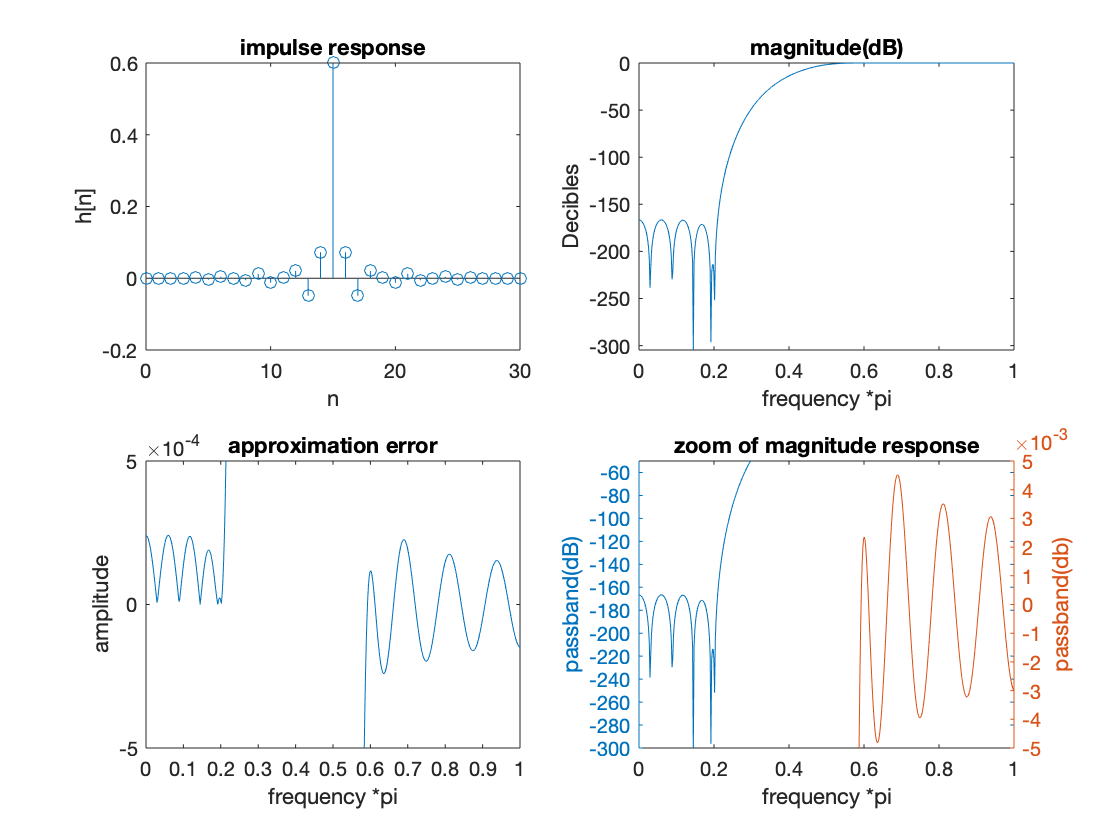

n=0:1:30;
hd=0.4*pi*(sinc(0.4*pi*(n-15))./pi);
w=kaiser0(31,4.5335);
h1=hd.*w; %與Kaider window相乘後的low pass filter
del=delta(0,15,30);
del=del';
h=del-h1; %將low pass filter轉為high pass
b = [0 0.3 0.5 1]; %輸入Ws和Wp的限制
a = [0 0 1 1];
bhi = fir2(30,b,a,kaiser(31,4.5335));
H=freqz(bhi,1);
H=H';
om=linspace(0,pi,512);
ideal_H=[zeros(1,157) NaN(1,97) ones(1,258)]; %創一個ideal的low pass filter
error=abs(H)-ideal_H; %把設計好的filter與ideal filter相減得error
Hr=20*log(abs(H));
H_zoom_r=[Hr(1:157) NaN(1,355)]; %此為待會zoom in所需的圖形
H_zoom_l=[NaN(1,253) Hr(254:512)];
figure
subplot(221)
stem(n,h)
title('impulse response')
xlabel('n')
ylabel('h[n]')
subplot(222)
plot(om/pi,20*log(abs(H)))
title('magnitude(dB)');
xlabel('frequency *pi')
ylabel('Decibles')
subplot(223)
plot(om/pi,error)
ylim([-0.0005, 0.0005]);
xticks([0:0.1:1])
title('approximation error');
xlabel('frequency *pi')
ylabel('amplitude')
subplot(224)
[AX,H1,H2]=plotyy(om/pi,H_zoom_r,om/pi,H_zoom_l);
set(AX(2),'YLim',[-0.005 0.005])
set(AX(1),'YLim',[-300 -50])
set(AX(2),'YTick',[-0.005:0.001:0.005])
set(AX(1),'YTick',[-300:20:-50])
ylabel(AX(2),'passband(db)') % left y-axis
ylabel(AX(1),'passband(dB)') % right y-axis
title('zoom of magnitude response');
xlabel('frequency *pi')

(b)

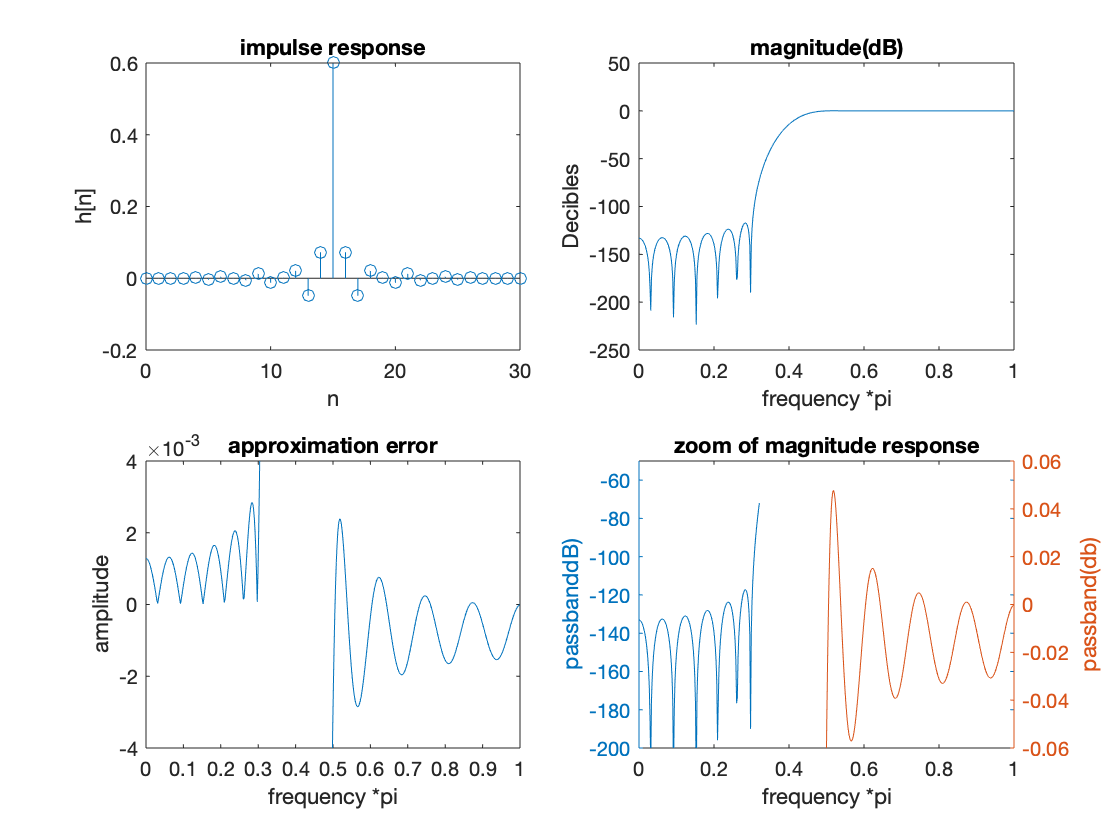

H=freqz(bhi,1);
n=0:1:30;
hd=0.4*pi*(sinc(0.4*pi*(n-15))./pi);
w=kaiser0(31,4.5335);
h1=hd.*w; %與Kaider window相乘後的low pass filter
del=delta(0,15,30);
del=del';
h=del-h1; %將low pass filter轉為high pass
bhi = fir1(30,0.4,'high',kaiser(31,4.5335)); %輸入Wc限制與設定為high pass
H=freqz(bhi,1);
H=H';
om=linspace(0,pi,512);
ideal_H=[zeros(1,157) NaN(1,97) ones(1,258)]; %創一個ideal的low pass filter
error=abs(H)-ideal_H; %把設計好的filter與ideal filter相減得error
Hr=20*log(abs(H));
H_zoom_r=[Hr(1:165) NaN(1,347)]; %此為待會zoom in所需的圖形
H_zoom_l=[NaN(1,253) Hr(254:512)];
figure
subplot(221)
stem(n,h)
title('impulse response')
xlabel('n')
ylabel('h[n]')
subplot(222)
plot(om/pi,20*log(abs(H)))
title('magnitude(dB)');
xlabel('frequency *pi')
ylabel('Decibles')
subplot(223)
plot(om/pi,error)
ylim([-0.004, 0.004]);
xticks([0:0.1:1])
title('approximation error');
xlabel('frequency *pi')
ylabel('amplitude')
subplot(224)
[AX,H1,H2]=plotyy(om/pi,H_zoom_r,om/pi,H_zoom_l);
set(AX(2),'YLim',[-0.06 0.06])
set(AX(1),'YLim',[-200 -50])
set(AX(2),'YTick',[-0.06:0.02:0.06])
set(AX(1),'YTick',[-200:20:-50])
ylabel(AX(2),'passband(db)') % left y-axis
ylabel(AX(1),'passbanddB)') % right y-axis
title('zoom of magnitude response');
xlabel('frequency *pi')

7.

(a)

h=[1 2 3 -2 5 -2 3 2 1];
n=0:1:8;
om=linspace(-2*pi,2*pi,512);
H=freqz(h,1,om);
A=amplresp(h,om);

*** Type-1 Linear-Phase Filter ***


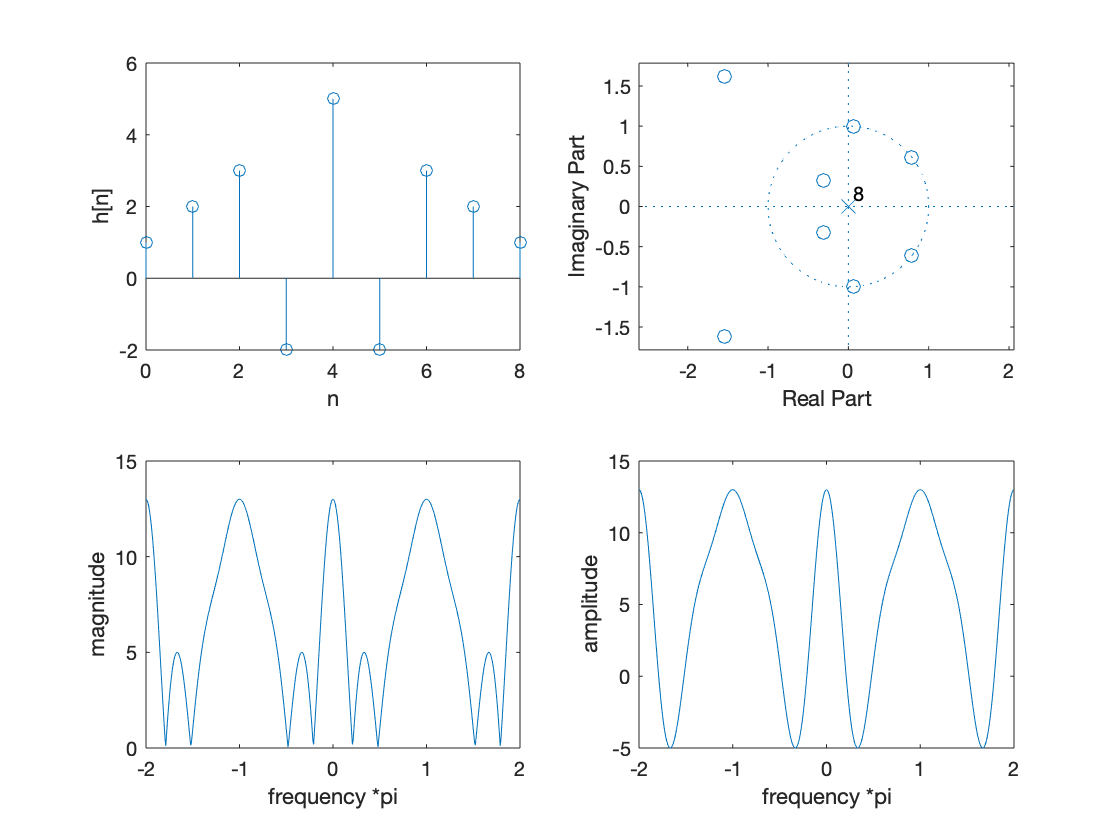

figure
subplot(221)
stem(n,h)
xlabel('n')
ylabel('h[n]')
subplot(222)
zplane(h,1)
subplot(223)
plot(om/pi,abs(H))
xlabel('frequency *pi')
ylabel('magnitude')
subplot(224)
plot(om/pi,A)
xlabel('frequency *pi')
ylabel('amplitude')

(b)

h=[1,2,3,-2,-2,3,2,1];
n=0:1:7;
om=linspace(-2*pi,2*pi,512);
H=freqz(h,1,om);
A=amplresp(h,om);

*** Type-2 Linear-Phase Filter ***


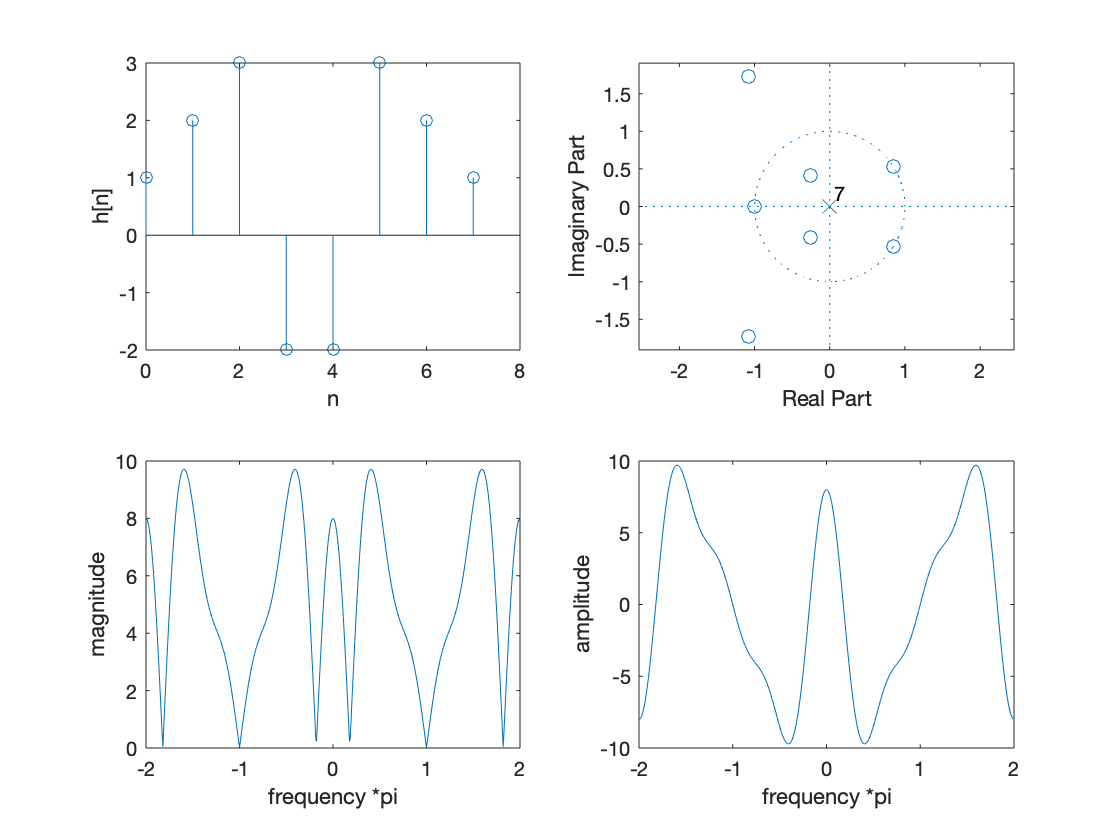

figure
subplot(221)
stem(n,h)
xlabel('n')
ylabel('h[n]')
subplot(222)
zplane(h,1)
subplot(223)
plot(om/pi,abs(H))
xlabel('frequency *pi')
ylabel('magnitude')
subplot(224)
plot(om/pi,A)
xlabel('frequency *pi')
ylabel('amplitude')

(c)

h=[1,2,3,-2,0,2,-3,-2,-1];
n=0:1:8;
om=linspace(-2*pi,2*pi,512);
H=freqz(h,1,om);
A=amplresp(h,om);

*** Type-3 Linear-Phase Filter ***


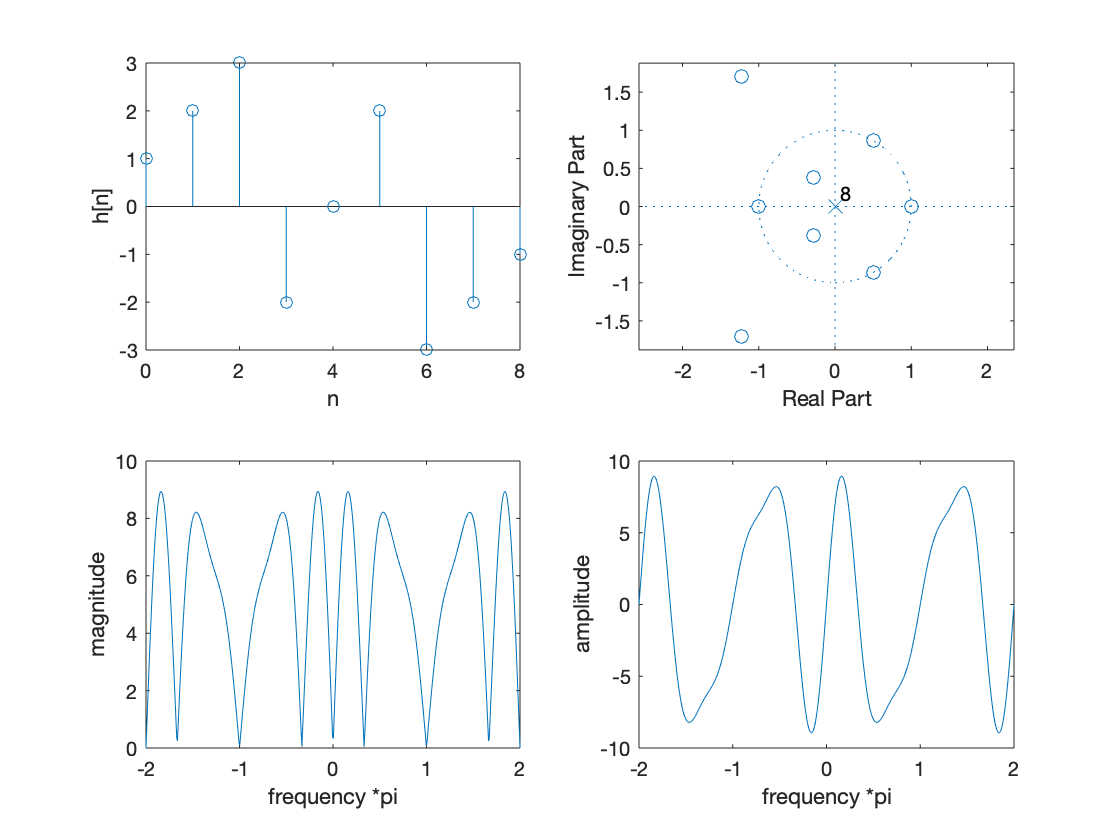

figure
subplot(221)
stem(n,h)
xlabel('n')
ylabel('h[n]')
subplot(222)
zplane(h,1)
subplot(223)
plot(om/pi,abs(H))
xlabel('frequency *pi')
ylabel('magnitude')
subplot(224)
plot(om/pi,A)
xlabel('frequency *pi')
ylabel('amplitude')

(d)

h=[1,2,3,-2,2,-3,-2,-1];
n=0:1:7;
om=linspace(-2*pi,2*pi,512);
H=freqz(h,1,om);
A=amplresp(h,om);

*** Type-4 Linear-Phase Filter ***


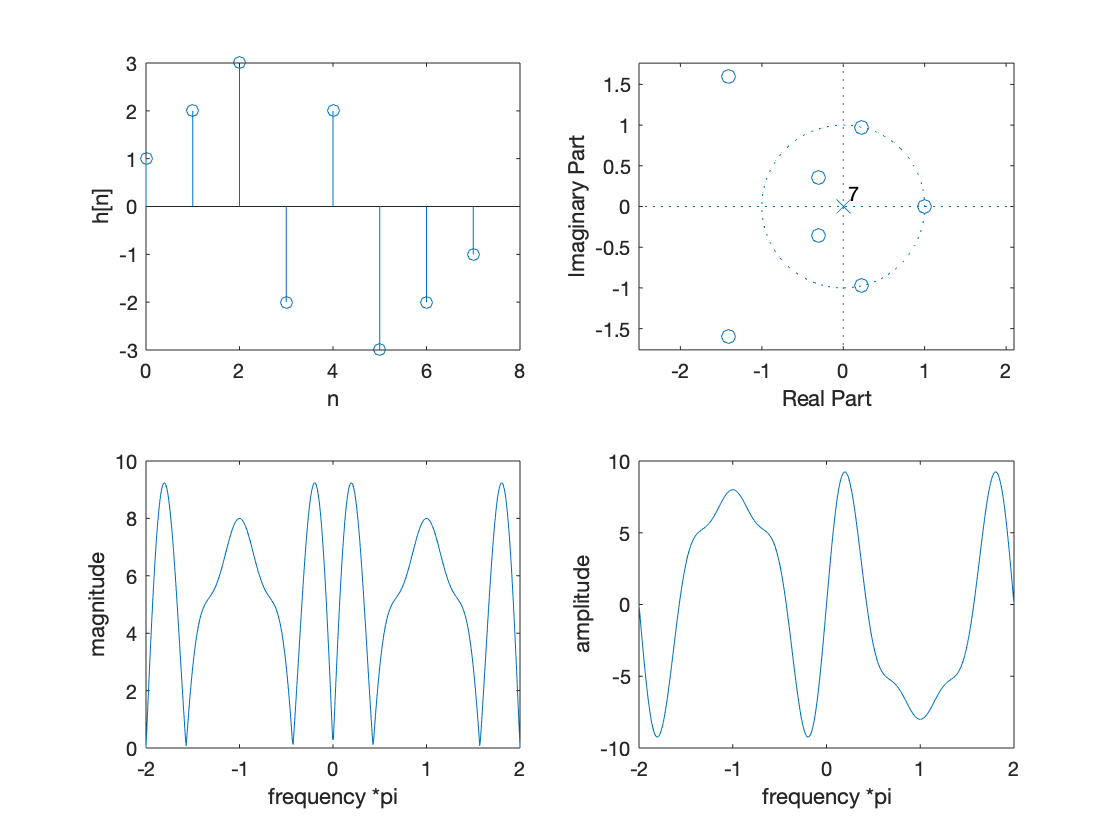

figure
subplot(221)
stem(n,h)
xlabel('n')
ylabel('h[n]')
subplot(222)
zplane(h,1)
subplot(223)
plot(om/pi,abs(H))
xlabel('frequency *pi')
ylabel('magnitude')
subplot(224)
plot(om/pi,A)
xlabel('frequency *pi')
ylabel('amplitude')

8.

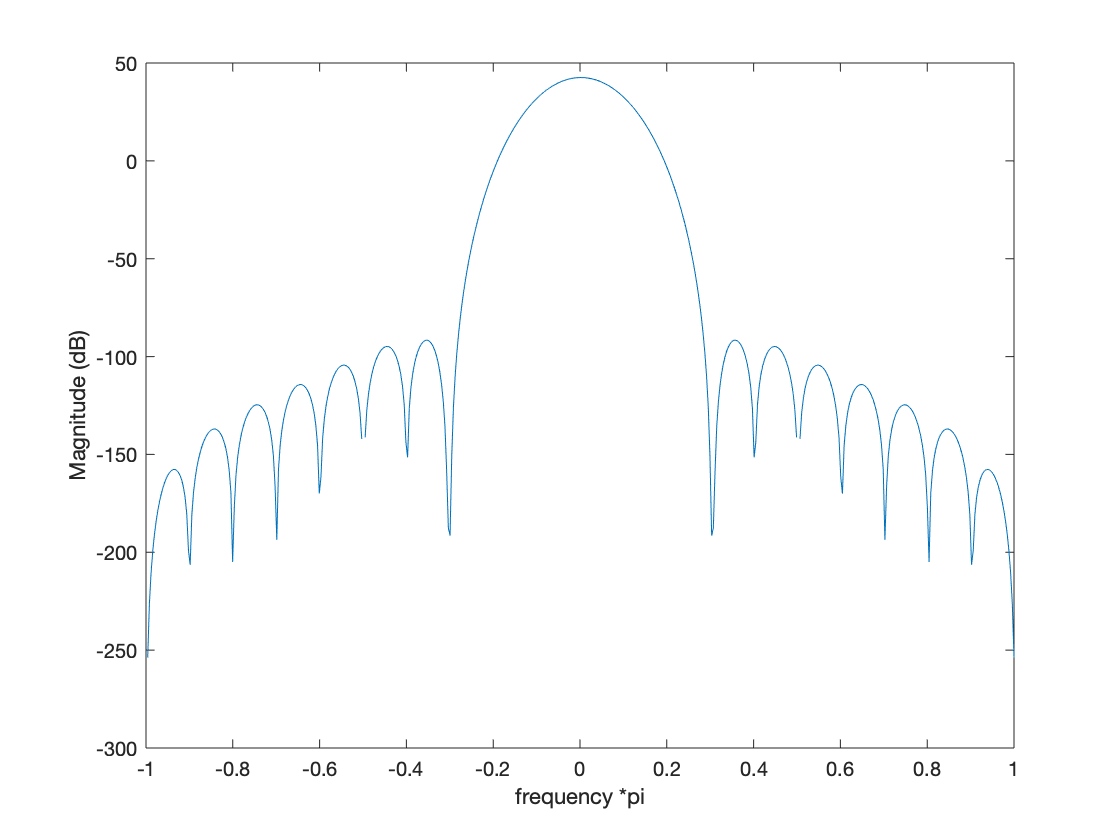

w = blackman(21);
om=linspace(-pi,pi,512);
W = fft(w,512);           % Blackman window transform
W=fftshift(W);
figure
plot(om/pi,20*log(abs(W))); 
xlabel('frequency *pi');
ylabel('Magnitude (dB)');

[y,x]=findpeaks(20*log(abs(W)))

y =  -157.6811
 -136.9872
 -124.6345
 -114.2693
 -104.3781
  -94.8237
  -91.5858
   42.5646
  -91.5858
  -94.8237


x =     18
    41
    66
    92
   117
   143
   166
   257
   348
   371


first sidelobe的最大值為-91.5858(dB)

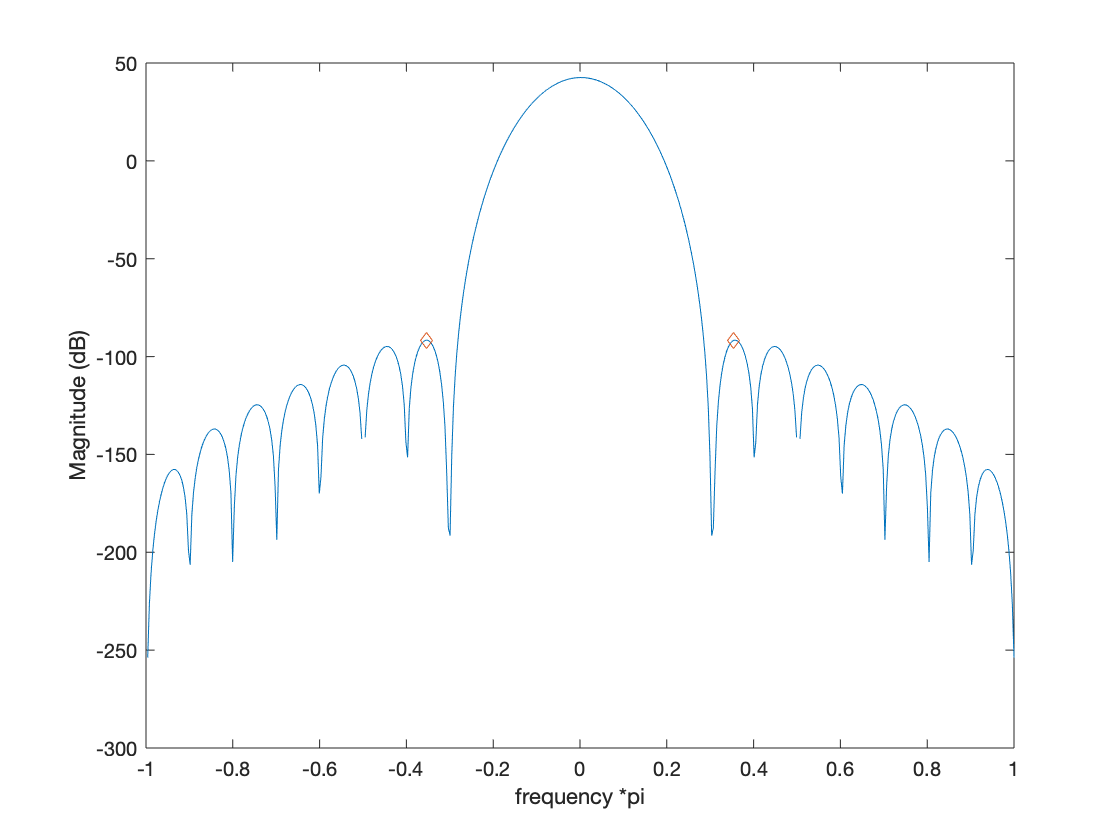

maxy=[NaN(1,165) -91.5858 NaN(1,180) -91.5858 NaN(1,165)];
figure
plot(om/pi,20*log(abs(W)),om/pi,maxy,'diamond');
xlabel('frequency *pi');
ylabel('Magnitude (dB)');

(b)

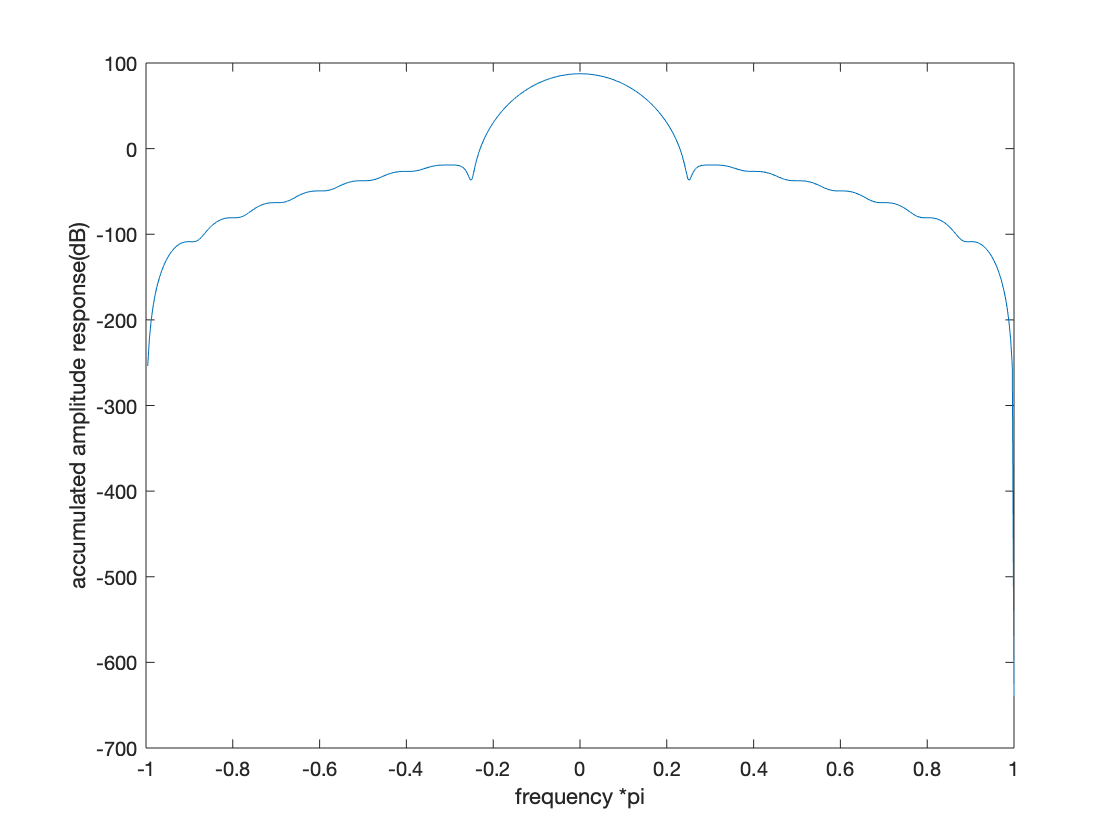

w = blackman(21);
om=linspace(-pi,pi,512);
W = fft(w,512);           % Blackman window transform
W=fftshift(W);
sum=cumsum(W);
figure
plot(om/pi,20*log(abs(sum)))
xlabel('frequency *pi');
ylabel('accumulated amplitude response(dB)');

[y,x]=findpeaks(20*log(abs(sum)))

y =  -108.6418
  -80.7355
  -63.1085
  -49.3906
  -26.5919
  -19.1396
   87.4293
  -19.1396
  -26.5919
  -49.3906


x =     26
    52
    77
   103
   154
   178
   256
   335
   359
   410


first sidelobe的最大值為-19.1396(dB)

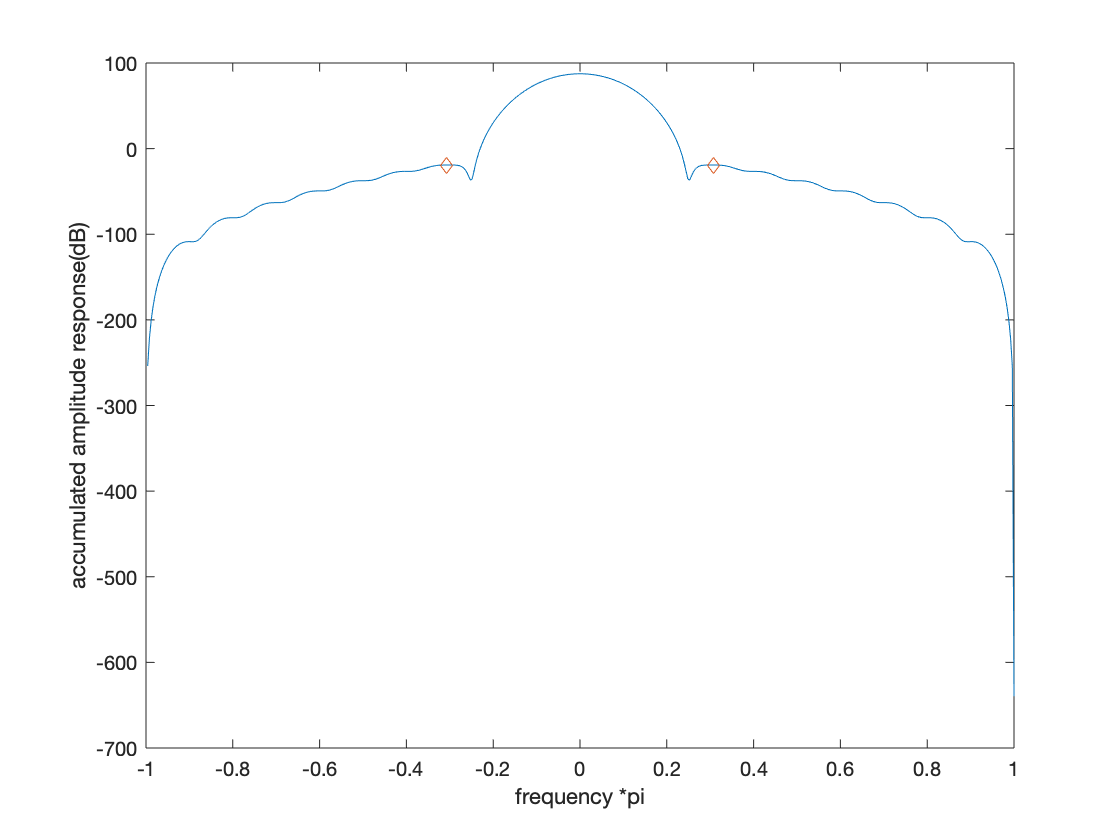

maxy=[NaN(1,177) -19.1396 NaN(1,156) -19.1396 NaN(1,177)];
figure
plot(om/pi,20*log(abs(sum)),om/pi,maxy,'diamond');
xlabel('frequency *pi');
ylabel('accumulated amplitude response(dB)');

(c)

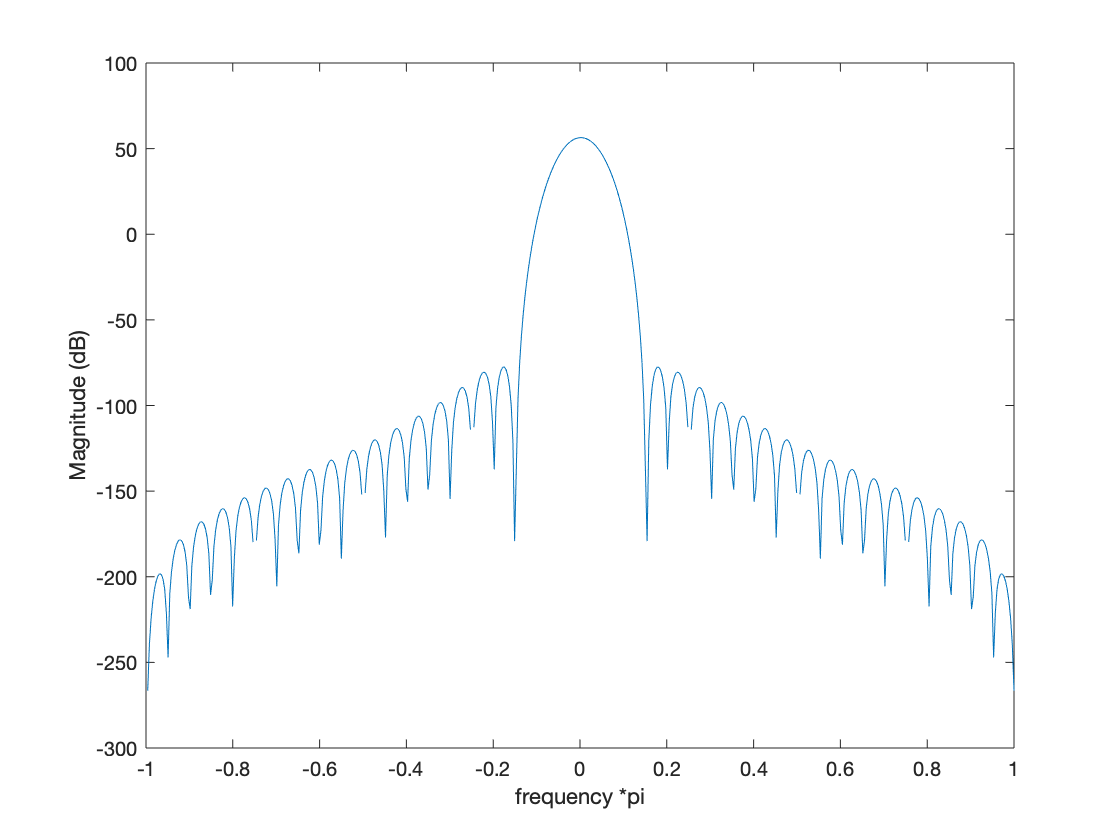

w = blackman(41);
om=linspace(-pi,pi,512);
W = fft(w,512);           % Blackman window transform
W=fftshift(W);
figure
plot(om/pi,20*log(abs(W))); 
xlabel('frequency *pi');
ylabel('Magnitude (dB)');

[y,x]=findpeaks(20*log(abs(W)))

y =  -198.2328
 -178.3805
 -167.9020
 -160.1759
 -153.8097
 -148.1436
 -142.8031
 -137.3719
 -131.8228
 -126.0724


x =      9
    21
    34
    46
    59
    72
    85
    97
   110
   123


first sidelobe的最大值為-77.5243(dB)

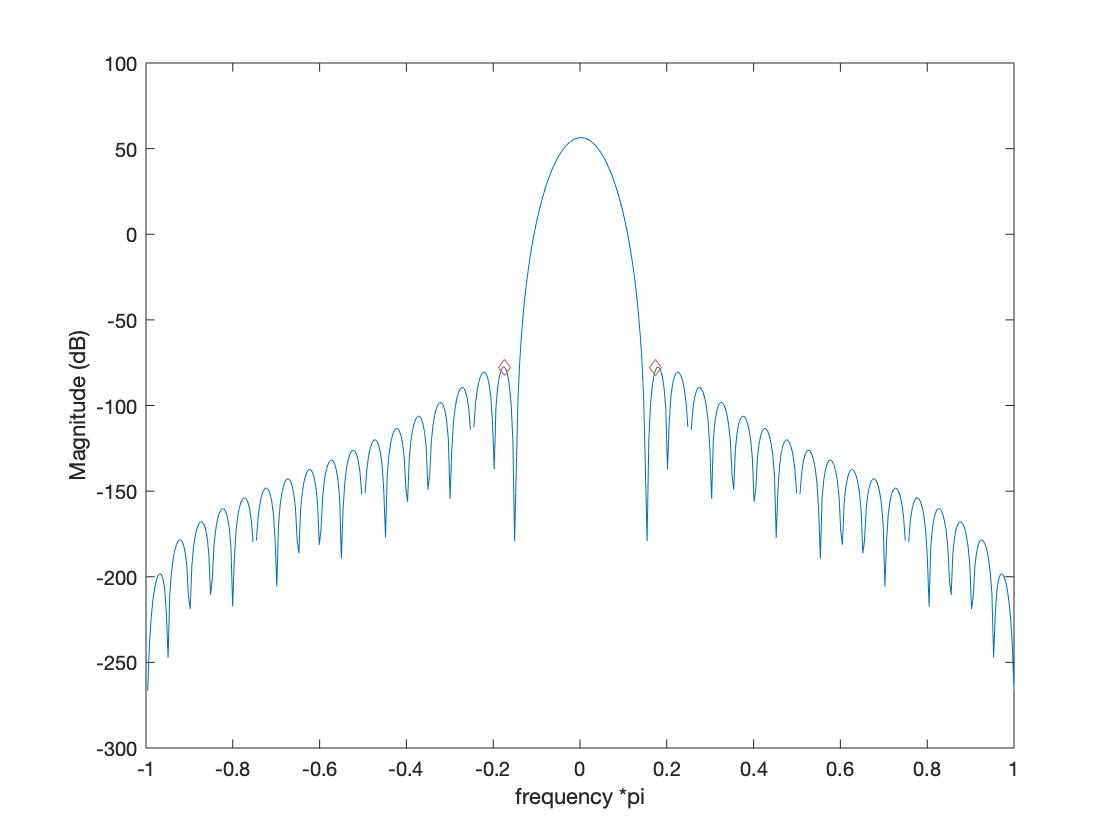

maxy=[NaN(1,211) -77.5243 NaN(1,88) -77.5243 NaN(1,211)];
figure
plot(om/pi,20*log(abs(W)),om/pi,maxy,'diamond');
xlabel('frequency *pi');
ylabel('Magnitude (dB)');

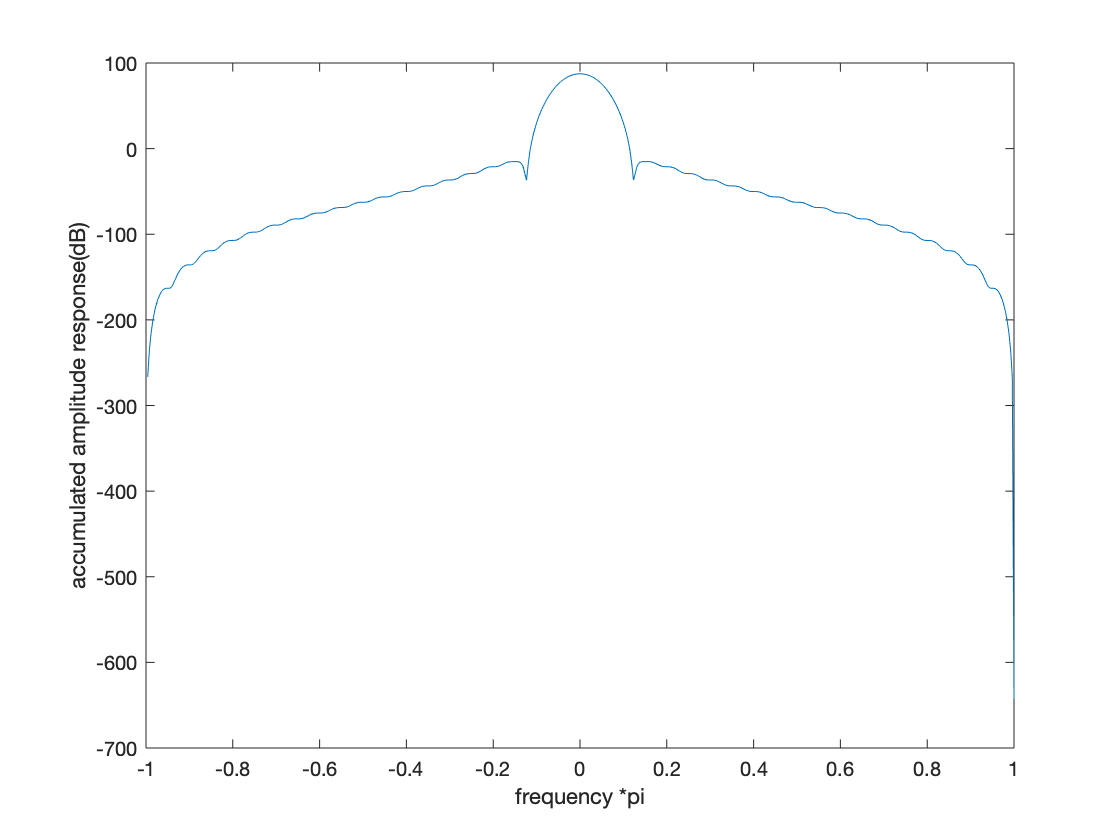

w = blackman(41);
om=linspace(-pi,pi,512);
W = fft(w,512);           % Blackman window transform
W=fftshift(W);
sum=cumsum(W);
figure
plot(om/pi,20*log(abs(sum)))
xlabel('frequency *pi');
ylabel('accumulated amplitude response(dB)');

[y,x]=findpeaks(20*log(abs(sum)))

y =  -163.0170
 -135.7600
  -89.3190
  -21.1634
  -15.1498
   87.4267
  -15.1498
  -21.1634
  -89.3190
 -135.7600


x =     13
    26
    77
   205
   217
   256
   296
   308
   436
   487


first sidelobe的最大值為-15.1498(dB)

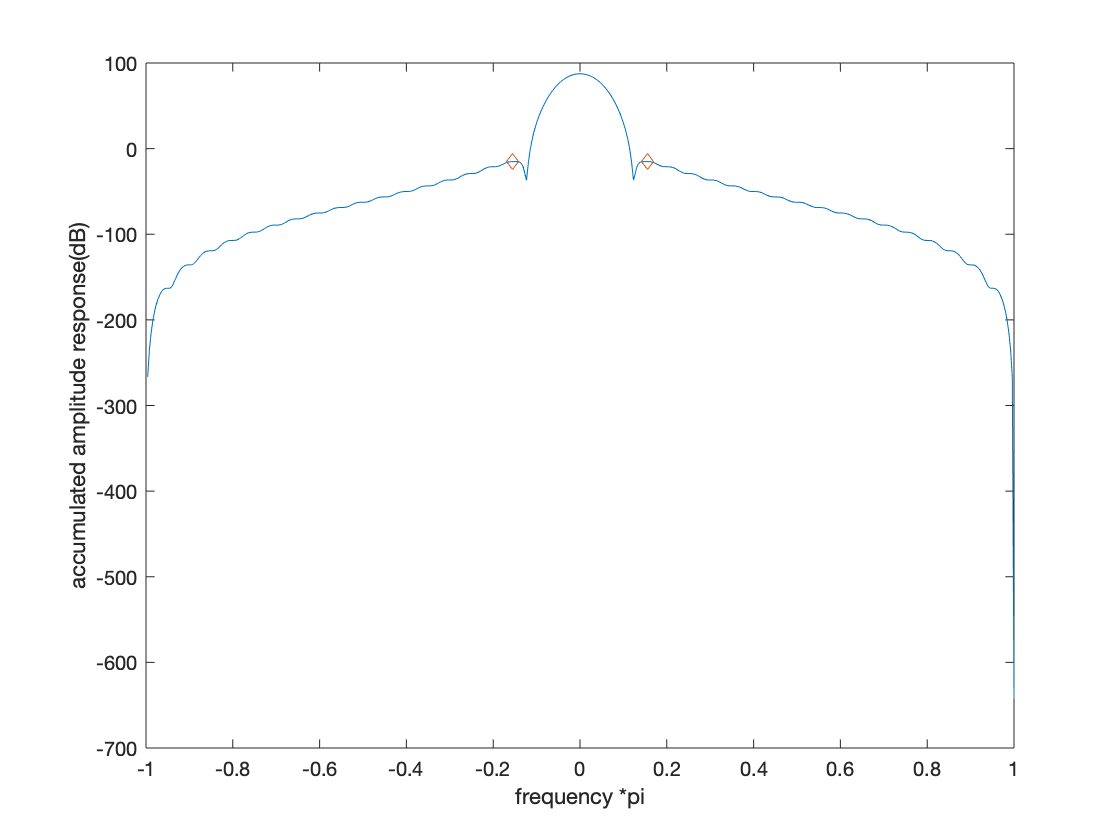

maxy=[NaN(1,216) -15.1498 NaN(1,78) -15.1498 NaN(1,216)];
figure
plot(om/pi,20*log(abs(sum)),om/pi,maxy,'diamond');
xlabel('frequency *pi');
ylabel('accumulated amplitude response(dB)');

9.

(a)

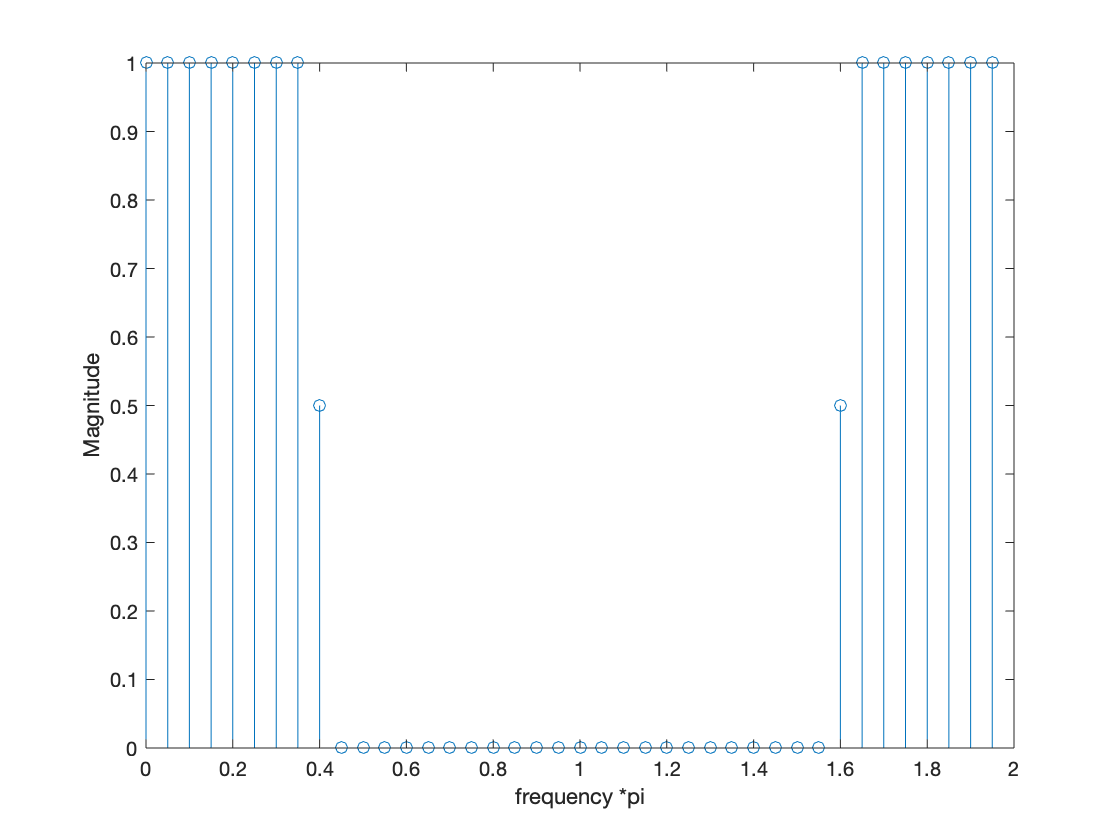

n=0:1:39;
L=40;
M=39;
alpha=M/2;
Q=floor(alpha);
om=linspace(0,2*pi,1001);
k=0:M;
psid=-alpha*2*pi/L*[(0:Q),-(L-(Q+1:M))];
Dw=2*pi/L;
k1=floor(wp/Dw);
k2=ceil(ws/Dw);
w=((k2-1):-1:(k1+1))*Dw;
Ad1=[ones(1,k1+2),0.5,zeros(1,L-2*k2+3),0.5,ones(1,k1+1)];
figure
stem(n,Ad1)
xticks([0:4:40])
xticklabels({'0','0.2','0.4','0.6','0.8','1','1.2','1.4','1.6','1.8','2'})
xlabel('frequency *pi');
ylabel('Magnitude');

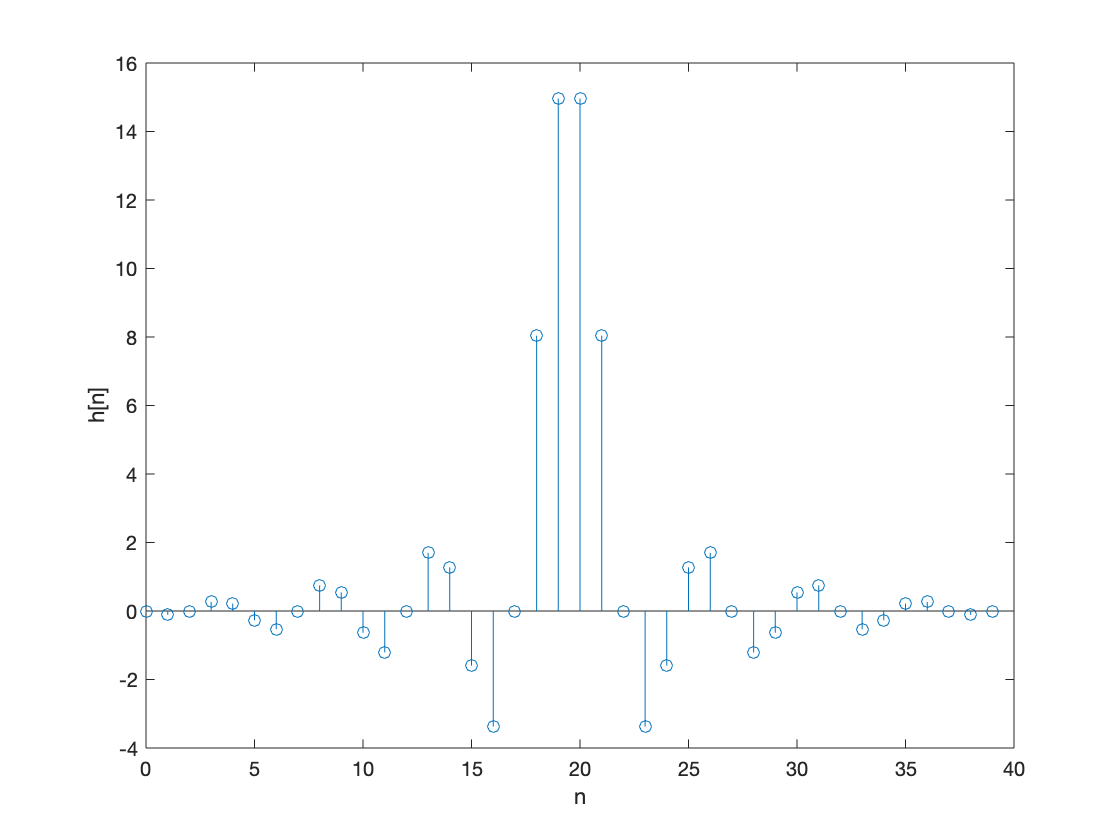

Hd1=Ad1.*exp(1i*psid);
hd1=real(ifft(Hd1));
h1=hd1.*(L)';
figure
stem(n,h1)
xlabel('n');
ylabel('h[n]');

H1=freqz(h1,1,om);
H1=H1/L;
maxmag=max(abs(H1));
dw=2*pi/1000;
Asd1=min(-20*log10(abs(H1(ceil(ws/dw):501))/maxmag))

Asd1 = 38.6067

minimum stopband attenuation:38.6067(dB)

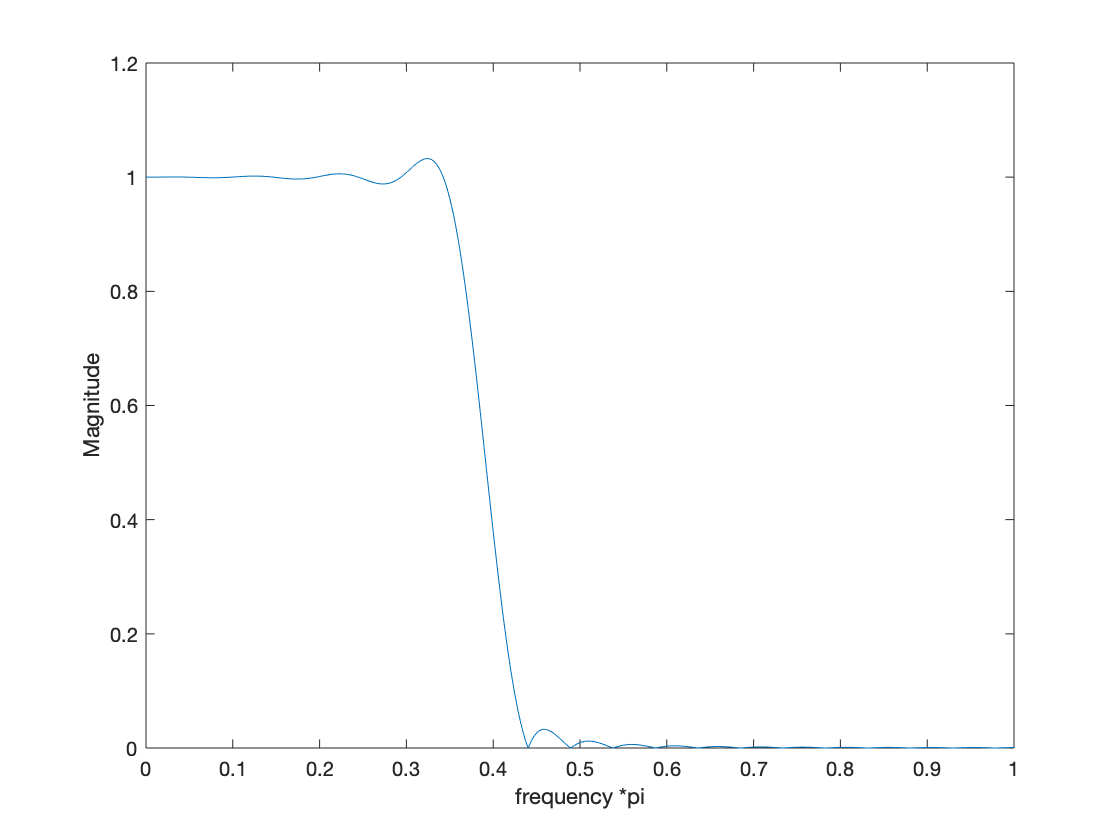

om=linspace(0,pi,512);
H1_half=H1(1:512);
figure
plot(om/pi,(abs(H1_half)))
xlabel('frequency *pi');
ylabel('Magnitude');

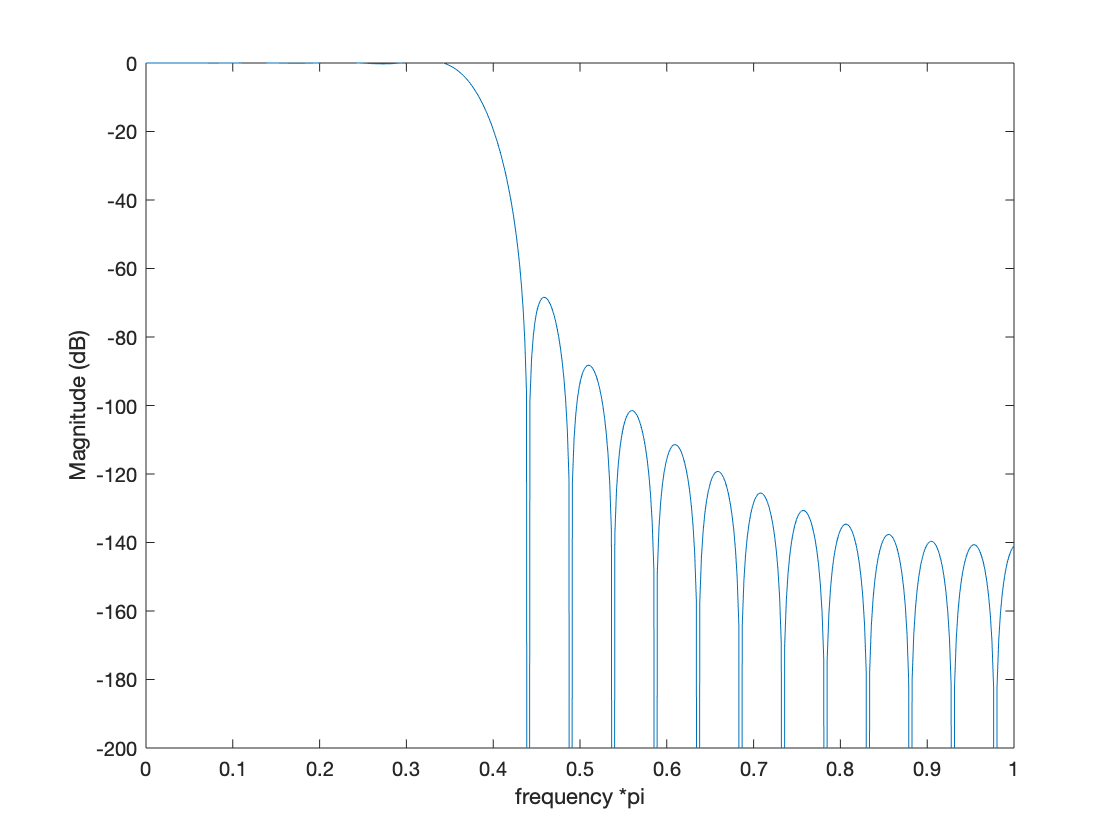

figure
plot(om/pi,20*log(abs(H1_half)))
ylim([-200, 0]);
xlabel('frequency *pi');
ylabel('Magnitude (dB)');

(b)

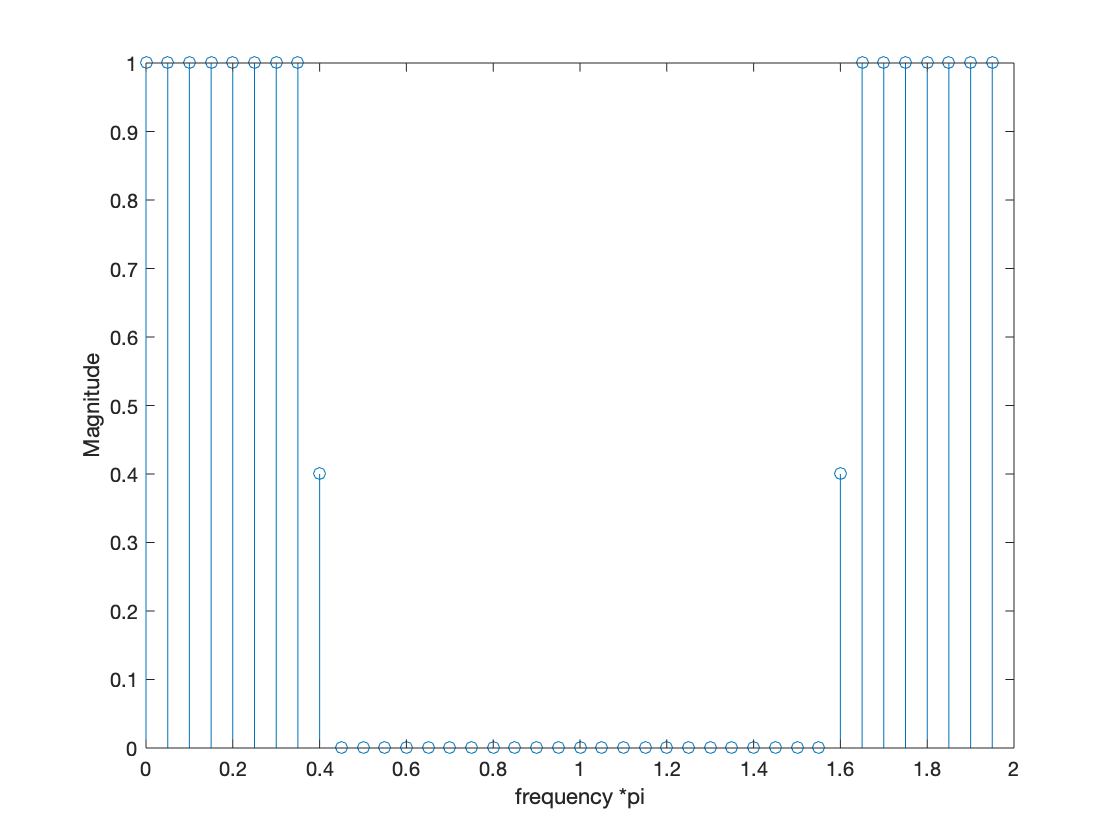

n=0:1:39;
L=40;
M=39;
alpha=M/2;
Q=floor(alpha);
om=linspace(0,2*pi,1001);
k=0:M;
psid=-alpha*2*pi/L*[(0:Q),-(L-(Q+1:M))];
Dw=2*pi/L;
k1=floor(wp/Dw);
k2=ceil(ws/Dw);
w=((k2-1):-1:(k1+1))*Dw;
Ad2=[ones(1,k1+2),0.4,zeros(1,L-2*k2+3),0.4,ones(1,k1+1)];
figure
stem(n,Ad2)
xticks([0:4:40])
xticklabels({'0','0.2','0.4','0.6','0.8','1','1.2','1.4','1.6','1.8','2'})
xlabel('frequency *pi');
ylabel('Magnitude');

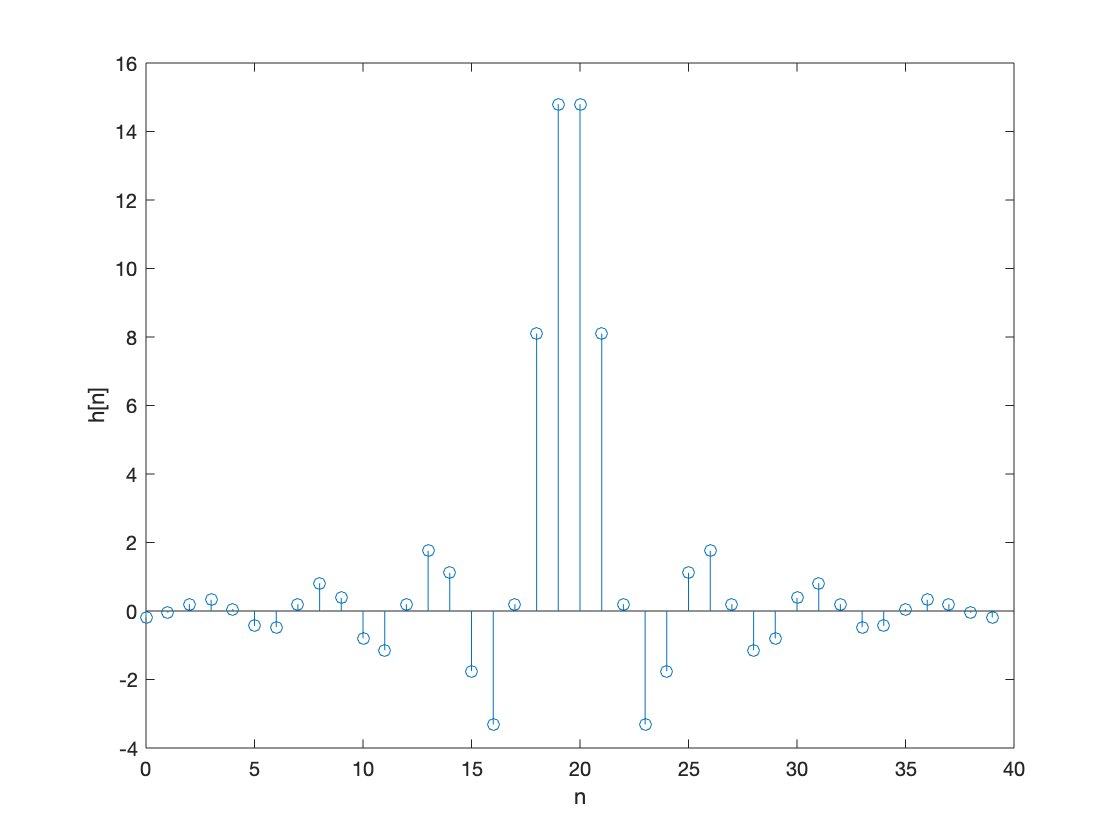

Hd2=Ad2.*exp(1i*psid);
hd2=real(ifft(Hd2));
h2=hd2.*(L)';
figure
stem(n,h2)
xlabel('n');
ylabel('h[n]');

H2=freqz(h2,1,om);
H2=H2/L;
maxmag=max(abs(H2));
dw=2*pi/1000;
Asd2=min(-20*log10(abs(H2(ceil(ws/dw):501))/maxmag))

Asd2 = 44.9600

當Wc的點為0.4時，有最大的minimum stopband attenuation:44.96(dB)

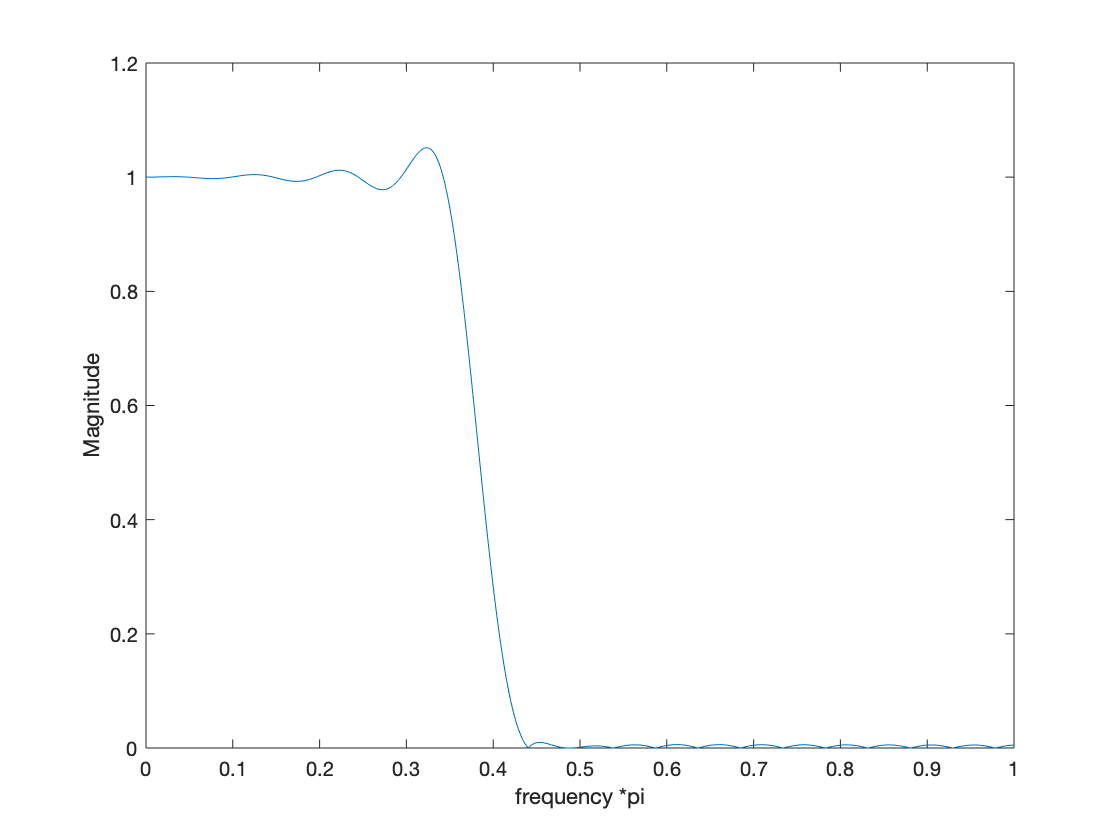

om=linspace(0,pi,512);
H2_half=H2(1:512);
figure
plot(om/pi,(abs(H2_half)))
xlabel('frequency *pi');
ylabel('Magnitude');

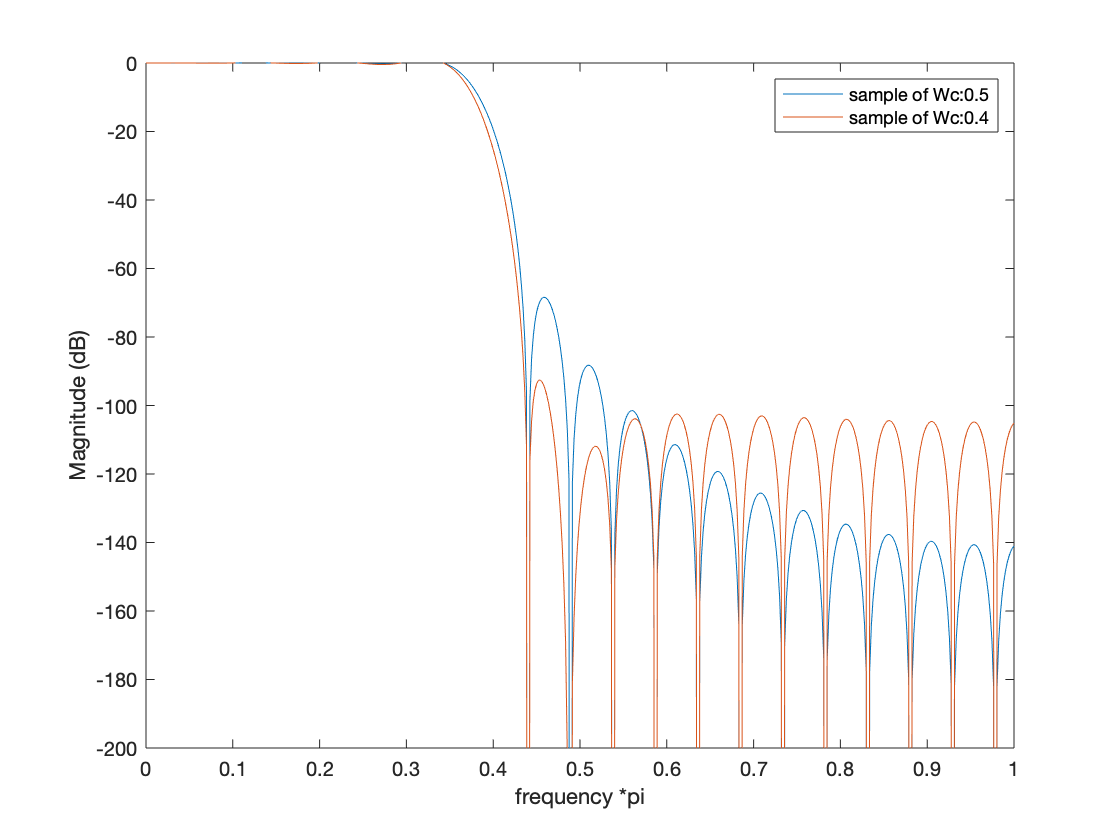

figure
plot(om/pi,20*log(abs(H1_half)),om/pi,20*log(abs(H2_half)))
ylim([-200, 0]);
xlabel('frequency *pi');
ylabel('Magnitude (dB)');
legend('sample of Wc:0.5','sample of Wc:0.4')

(c)

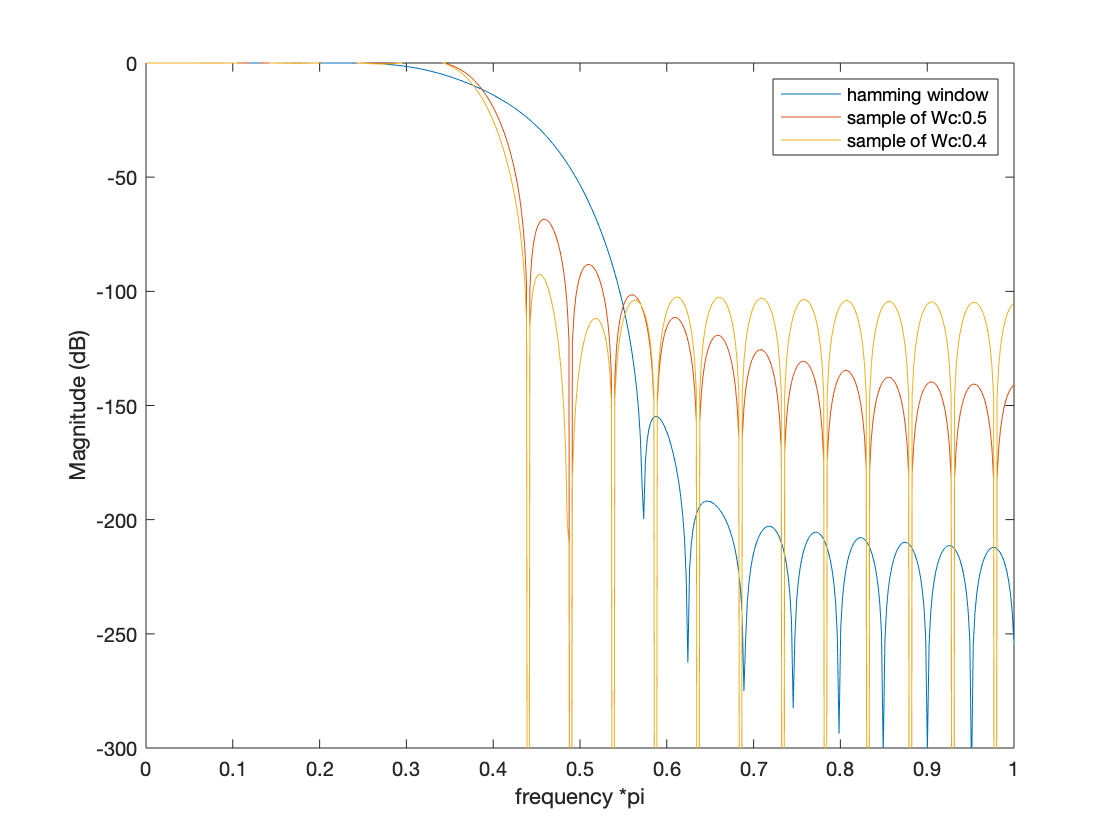

n=0:1:39;
b = [0 0.3 0.5 1];  %輸入Ws和Wp的限制
a = [1 1 0 0];
bhi = fir2(39,b,a,hamming(40));
H=freqz(bhi,1);
H=H';
figure
plot(om/pi,20*log(abs(H)),om/pi,20*log(abs(H1_half)),om/pi,20*log(abs(H2_half)))
ylim([-300, 0]);
xlabel('frequency *pi');
ylabel('Magnitude (dB)');
legend('hamming window','sample of Wc:0.5','sample of Wc:0.4')

hamming window在time domain的bandwidth較小，波形也比較smooth，從magnitude中可看出，hamming window的mainlobe比較寬，但相對的hamming window的sidelobe比其他兩個不管是Wc的sample點在0.5或0.4都還要小，符合預期